# Model Predictive Control

**author: Xin Lyu**

clear;
close all;


## define state

A = [1 0.1;0 2];
n =size(A,2);
B = [0;0.5];
p = size(B,2);

Q = eye(2);
F = eye(2)

F =      1     0
     0     1


R = 0.1

R = 0.1000


% define steps
k_steps = 100;

% define X_k (nxk) 
X_k = zeros(n,k_steps);
X_k(:,1) = [20,-20]

X_k =     20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   -20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% define U_k (pxk)
U_k = zeros(p,k_steps)

U_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


## Prediction Parameters

N = 5;
% Calculate E,H matrix
% E = C^T*Q_bar*M
% H = C^TQ_bar*C+R_bar
M = zeros((N+1)*n,n);
C = zeros((N+1)*n,N*p);
M(1:n,1:n) = eye(n);
for k = 1:N
    M(n+k*n-1:n+n*k,:) = A^k;  
    C(n+k*n-1:n+n*k,p) = A^(k-1)*B;
    C(n+k*n-1:n+n*k,p+1:end) = C(k*n-1:n*k,1:end-1);    
end
Q_b = kron(eye(N),Q);
Q_b = blkdiag(Q_b,F);
R_b = kron(eye(N),R);
E = C'*Q_b*M;
H = C'*Q_b*C+R_b;

## Prediction

for k =1:k_steps
   U_k(:,k) = Prediction(X_k(:,k),E,H,N,p);
    X_k(:,k+1) = (A*X_k(:,k)+B*U_k(:,k));
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

## Plot

subplot (2,1,1);
hold;

Current plot held


for i =1:size(X_k,1)
    plot(X_k(i,:));
end
legend('x1','x2');
hold off

subplot(2,1,2);
hold;

Current plot held


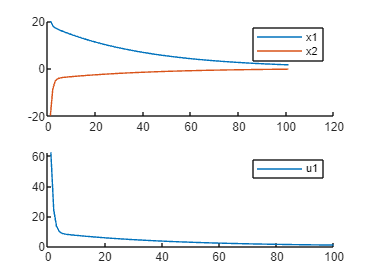

for i=1:size(U_k,1)
    plot(U_k(i,:));
end
legend('u1')